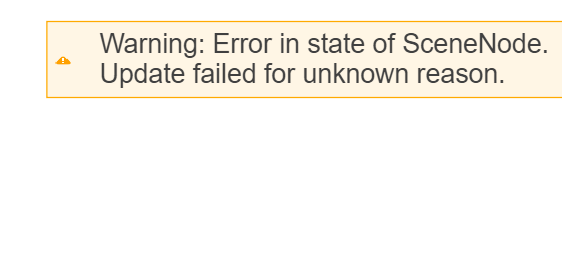

clear;
clc;
close all;

% Load image
image = im2double(imread("images/test.jpg"));

[rows,cols,channels]=size(image);

tileSize=0.25;
imgray=im2gray(image);
freImage=fft2(image);
shimage=fftshift(freImage);
magSpec = abs(shimage);
magWeight = mat2gray(log(1 + magSpec));
brightnessMask = imgaussfilt(magWeight, 2);

alphaFreq = 0.99; % Strength of frequency-based adjustment
adjustmentFactor = 1 + alphaFreq * (brightnessMask - mean(brightnessMask(:)));

imshow(adjustmentFactor)

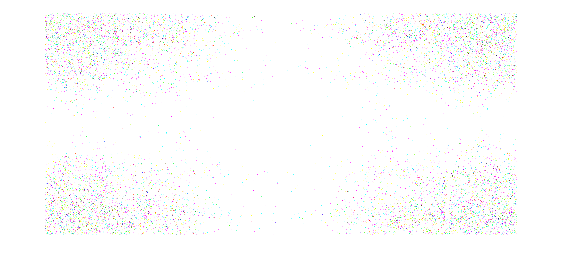

imshow(magSpec)

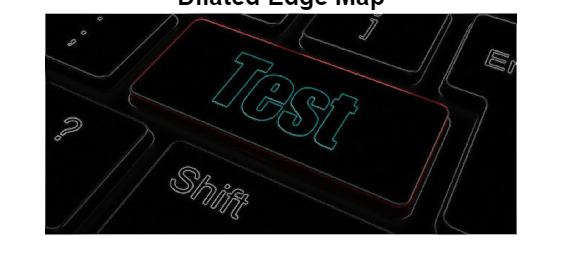

finalEdgeMap =createEdgeMap(image);

%finalEdgeMap =createEdgeMap(imgray);
